# 10.3 Optimal Control of Pitch/Travel with Feedback (LQ)

## **Load and extract data**

**Load simulink data from MAT-file**

% u_values = load("data/u_valueslab1.mat");
x_mat = load("data/x16.mat");
u_mat = load("data/u16.mat");

% OPTIMAL
x_data_opt = X_opt.data;

% Extract from Simulink
x_data = x_mat.data;
u_data = u_mat.data;

**Get U states**

u_time = u_data(1, :);
u_pitch = u_data(2, :);
u_elevation = u_data(3, :);

**Get optimal U states**

u_pitch_opt = Up_opt.data;
u_elevation_opt = Ue_opt.data;

**Get measured X states**

x_time = x_data(1, :);
x_travel = x_data(2, :);
x_travel_rate = x_data(3, :);
x_pitch = x_data(4, :);
x_pitch_rate = x_data(5, :);
x_elevation = x_data(6, :);
x_elevation_rate = x_data(7, :);

**Get optimal X states**

x_travel_opt = x_data_opt(:, 1);
x_travel_rate_opt = x_data_opt(:, 2);
x_pitch_opt = x_data_opt(:, 3);
x_pitch_rate_opt = x_data_opt(:, 4);
x_elevation_opt = x_data_opt(:, 5);
x_elevation_rate_opt = x_data_opt(:, 6);

## **Vizualization**

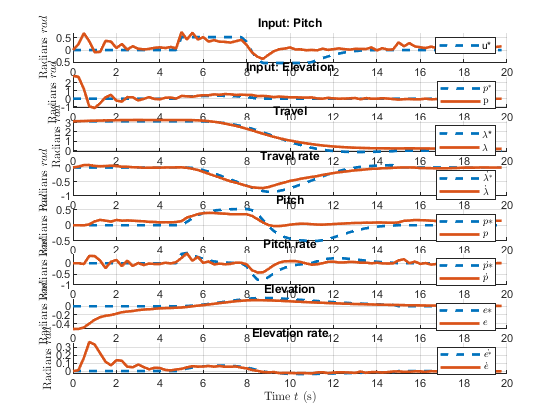

figure();

subplot(8, 1, 1);
hold on
grid on
plot(x_time, u_pitch_opt, "linewidth", 2, "linestyle","--");
plot(u_time, u_pitch, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('u*')
hold off
title("Input: Pitch")

subplot(8, 1, 2);
hold on
grid on
plot(x_time, u_elevation_opt, "linewidth", 2,"linestyle","--");
plot(x_time, u_elevation, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('$p^{*}$', 'p', "Interpreter", "latex")
hold off
title("Input: Elevation")

subplot(8, 1, 3);
hold on
grid on
plot(x_time, x_travel_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_travel, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('\lambda*', '\lambda') 
hold off
title("Travel")

subplot(8, 1, 4);
hold on
grid on
plot(x_time, x_travel_rate_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_travel_rate, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('$\dot{\lambda^{*}}$', '$\dot{\lambda}$',"Interpreter", "latex")
hold off
title("Travel rate")

subplot(8, 1, 5);
hold on
grid on
plot(x_time, x_pitch_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_pitch, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('$p*$', '$p$', "Interpreter", "latex") 
hold off
title("Pitch")

subplot(8, 1, 6);
hold on
grid on
plot(x_time, x_pitch_rate_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_pitch_rate, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('$\dot{p*}$', '$\dot{p}$', "Interpreter", "latex") 
hold off
title("Pitch rate")

subplot(8, 1, 7);
hold on
grid on
plot(x_time, x_elevation_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_elevation, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('$e*$', '$e$',"Interpreter", "latex")
hold off
title("Elevation")

subplot(8, 1, 8);
hold on
grid on
plot(x_time, x_elevation_rate_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_elevation_rate, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('$\dot{e^{*}}$', '$\dot{e}$',"Interpreter", "latex")
hold off
title("Elevation rate")

% saveas(gcf, "plots/lab3_sim_lab2p10.eps")